# Lab 1

Section 1: Examing sigma and probability of a normal distribution.

clc; clear; close all;
% Going to test out some code.

% Integrating the normal distribution.
a1 = normcdf(1); % z-table lookup is 0.84134
disp(a1);

    0.8413



a2 = normcdf(2); % z-table is 0.97725
disp(a2);

    0.9772



a3 = normcdf(-1); % calculated 0.1587 from z-table values
disp(a3);

    0.1587




% Finding sigma from probability.
b1 = norminv(0.84134); % expecting 1
disp(b1);

    1.0000



b2 = norminv(0.97725); % expecting 2
disp(b2);

    2.0000



b3 = norminv(2.86652E-7); % expecting 5 sigma
disp(b3);

   -5.0000



The sign on norminv() output tells us the direction from the mean.  Negative sigma will go to the left. The sign must be observed to determine the correct location on the distribution. (May just be intersted in the magnitude?)

Section 2:

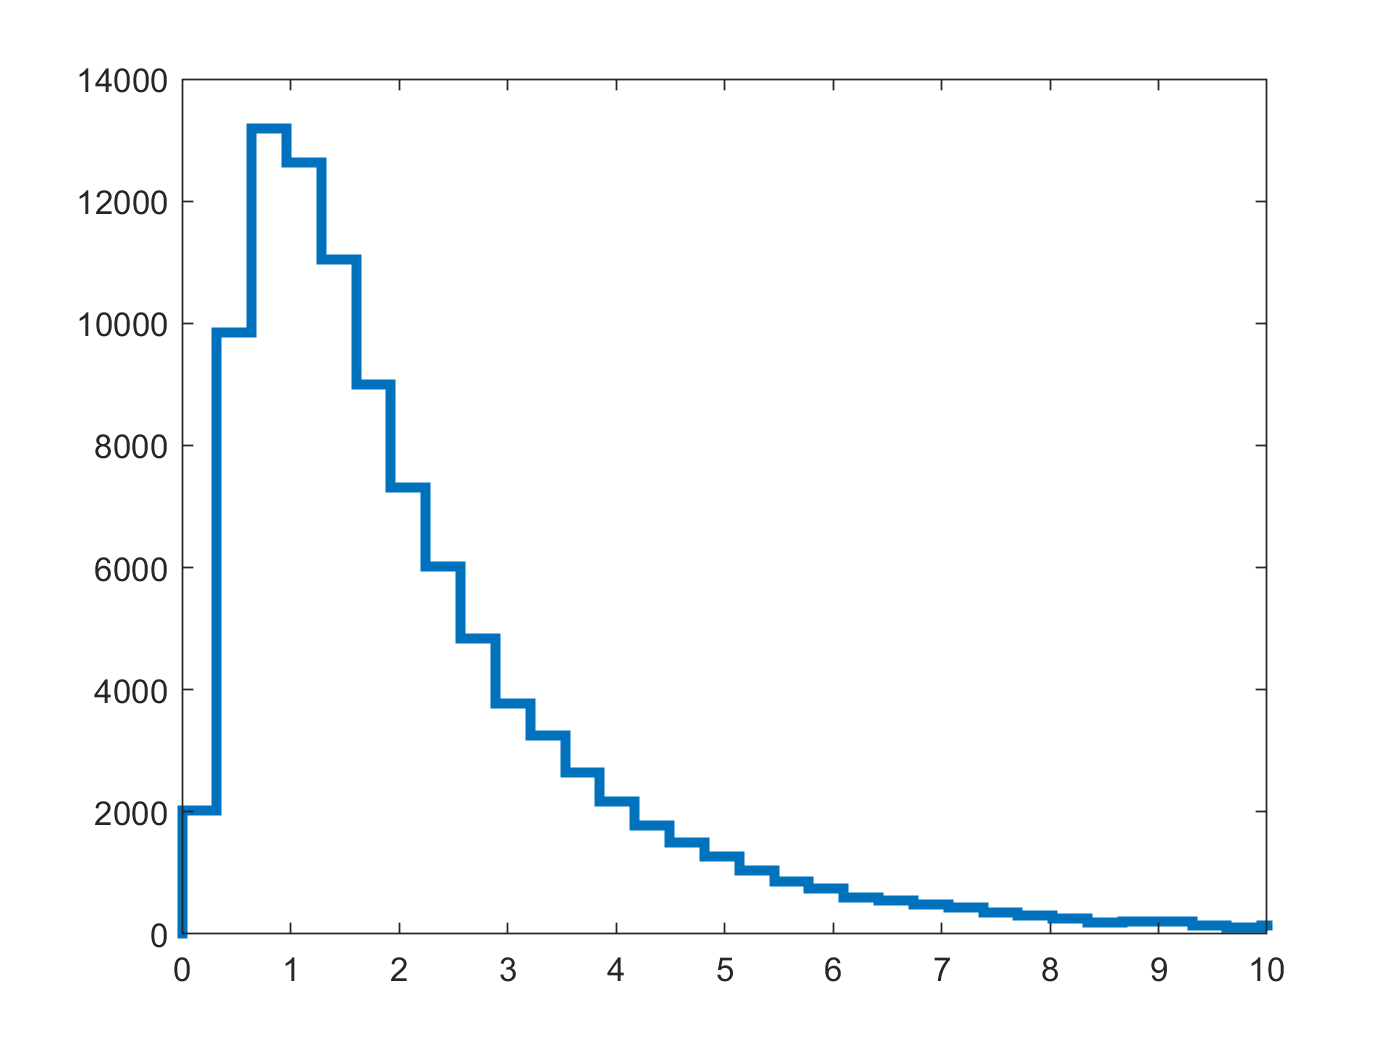

clc; clear; close all;
% x = linspace(-10,10,1000);
% normtest = makedist("Normal","mu",0,"sigma",1);
% plot(x,pdf(normtest, x),"LineWidth",4);
% xlim([-5,5]);
% ylim([0,1]);

% TA Question: analytic pdf() VERSUS samples w/ built-in distribution
mu = 0.5;
sigma = 0.8;

logNorm = random('Lognormal',mu,sigma,[1,100000]);
histogram(logNorm,200,'DisplayStyle',"stairs",'LineWidth',3);
xlim([0,10]);

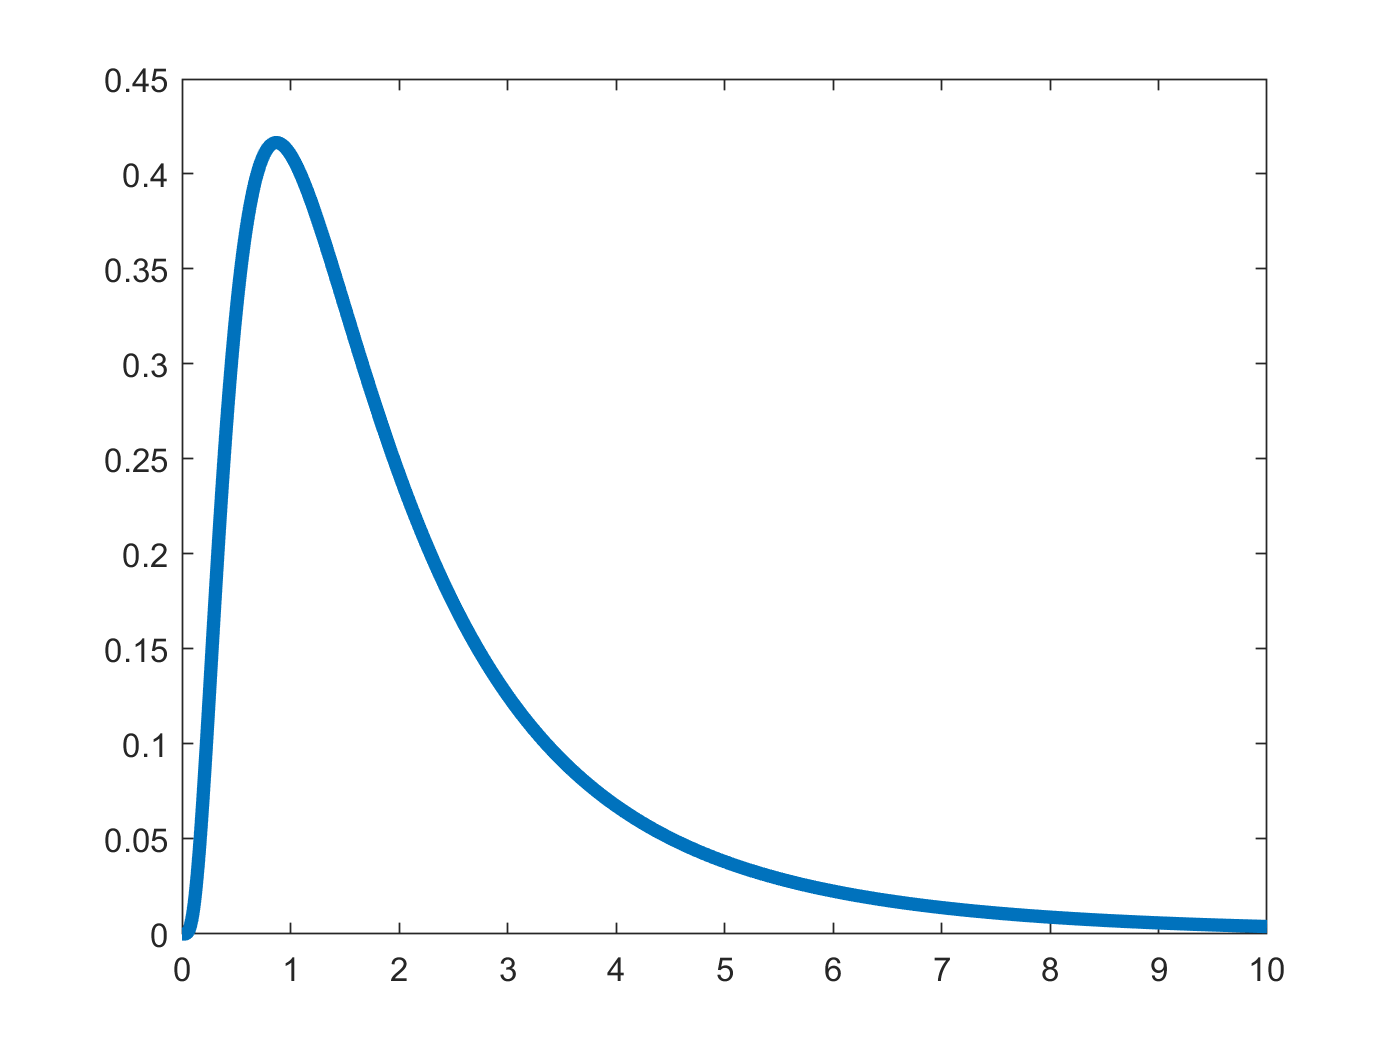


x = linspace(0,10,1000);
logN = makedist("Lognormal",'mu',mu,'sigma',sigma);
plot(x,pdf(logN,x),"LineWidth",4);

Section 3:

I will select for the value 9.

What is the likelihood that the random signal-free data will produce a value equal to or greater than 9?

Integral:

Probability calculation:

y = 1 - cdf(logN,9);

Finding 'sigma':

% Is this the sigma of a normal distribution, always?
c1 = norminv(y);

Equivalent is just over two sigma.

Section 4: Exploration and Patterns.